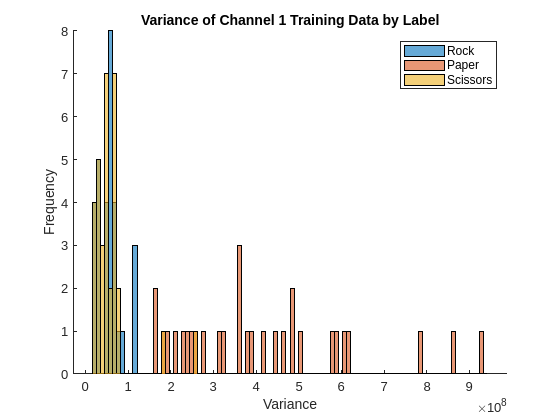

load("anotherDay.mat");

plot_features(feature_table.variance_Ch1, labels, "Variance")

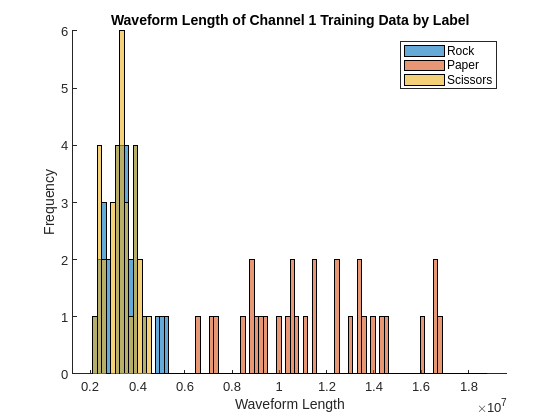

plot_features(feature_table.waveformlength_Ch1, labels, "Waveform Length")

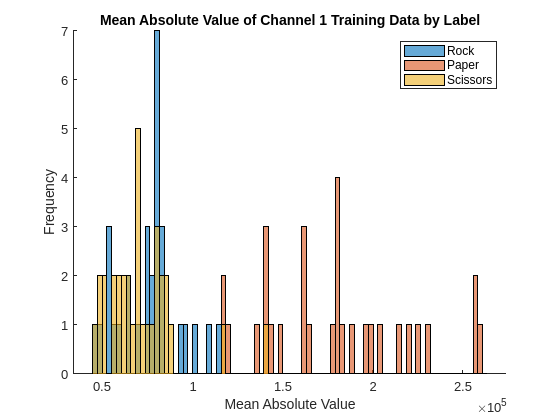

plot_features(feature_table.meanabsvalue_Ch1, labels, "Mean Absolute Value")

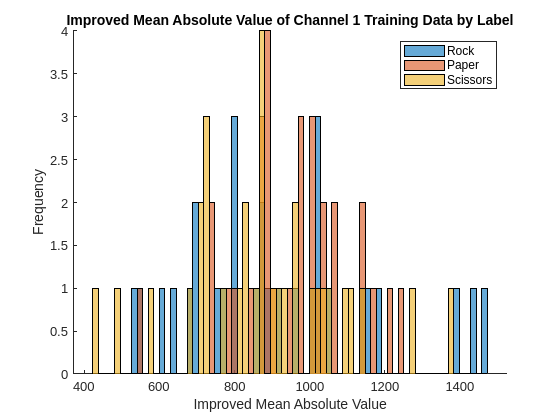

plot_features(feature_table.improved1meanabsvalue_Ch1, labels, "Improved Mean Absolute Value")

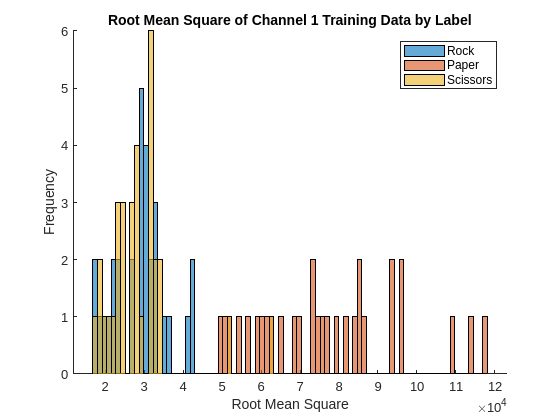

plot_features(feature_table.rootmeansquare_Ch1, labels, "Root Mean Square")

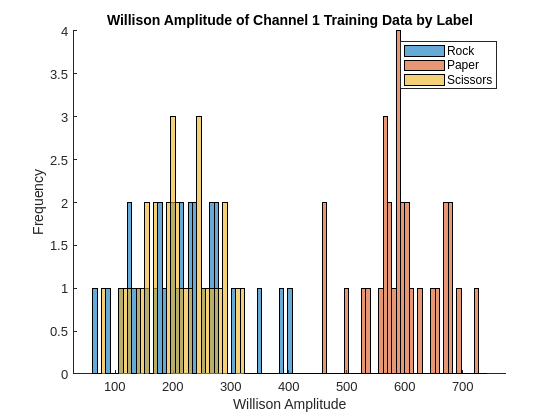

plot_features(feature_table.willisonamp_Ch1, labels, "Willison Amplitude")

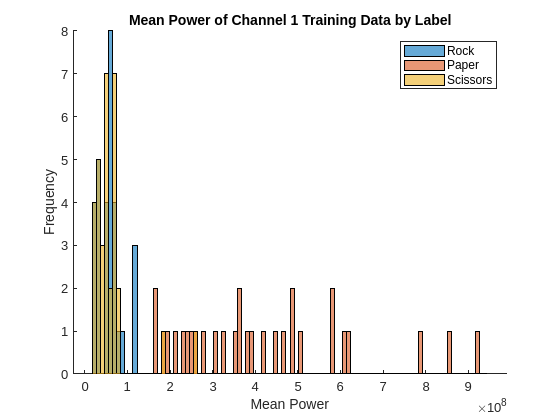

plot_features(feature_table.meanpower_Ch1, labels, "Mean Power")

function [] = plot_features(feature_arr, labels, feature_name)
    figure(); hold on;
    title(strcat(feature_name, " of Channel 1 Training Data by Label"));
    for cond=1:3
        histogram(feature_arr(labels==cond), 'BinEdges', min(feature_arr):max(feature_arr)/100:max(feature_arr))
    end
    xlabel(feature_name)
    ylabel("Frequency")
    legend(string(["Rock","Paper","Scissors"]));
    exportgraphics(gcf, strcat(feature_name,".png"),'Resolution',300)
    close(gcf);
end